## DKE Introduction to Bioinformatics 2022

# Gene expression data

This week we're going to look at a microarray dataset, preprocess the data and generate a list of differentially expressed genes.  This dataset was generated from a breast cancer cell line (MCF7) which was grown in the lab.  There were samples taken after 0h, 8h 24h and 32h (called reox), for the first 24hrs the cells were starved of oxygen, then after 24hrs the oxygen was returned to the cells for 8hrs before the final timepoint.  There are 3 samples taken at each timepoint, and we want to look at how oxygen deprivation affects the genes being expressed. 

The data can be found in the file MCF7_HypoxiaExperiment_RawExpressionData.txt 

- Read this file into Matlab and take a look at it. 

data = readtable("MCF7_HypoxiaExperiment_RawExpressionData.txt")

data = 22732×13 table
      Ensembl_Gene_ID      Expr_t0_I    Expr_t0_II    Expr_t0_III    Expr_t8_I    Expr_t8_II    Expr_t8_III    Expr_t24_I    Expr_t24_III    Expr_t24_IIII    Expr_treox_I    Expr_treox_II    Expr_treox_III
    ___________________    _________    __________    ___________    _________    __________    ___________    __________    ____________    _____________    ____________    _____________    ______________

    {'ENSG00000000003'}        6.5        6.9019        6.5051        6.6443        6.9393        6.4321         6.1512    

Each row of the table is a gene, with a given Ensemble Gene ID.  The experiments are labelled in the columns - make sure you can match the sample labels to the description of the experiment design in the paragraph above.  The numbers are a reading of how much luminesence was seen on spots where RNA from that gene would have attached.  A higher number means there was more RNA from that gene present in the sample.  The values given are already log transformed, log base 2.

  We need to normalise the data before it can be used.

2. a. Make a box plot showing the range of values for each sample.  Explain how this plot indicates the need for normalisation.

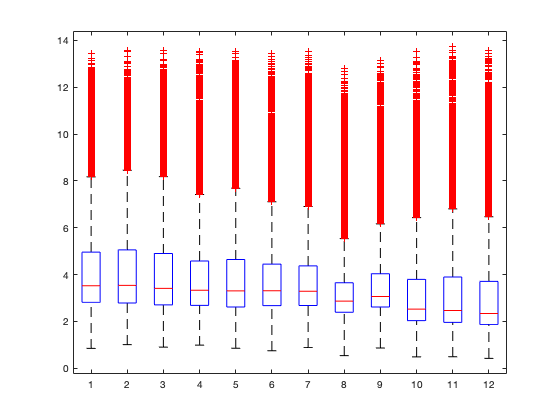

figure;
boxplot(table2array(data(1:22732, 2:13)))

b. Normalise the date using **quantilenorm** and then remake the boxplot to visualise the effect of your normalisation procedure. Explain what this procedure has done to your data.

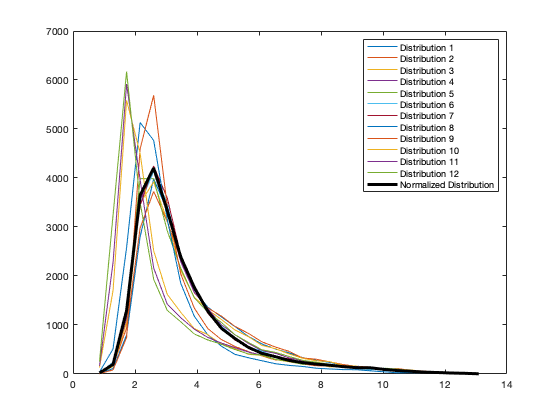

normalised = quantilenorm(table2array(data(1:22732, 2:13)), 'MEDIAN', true, 'DISPLAY', true);

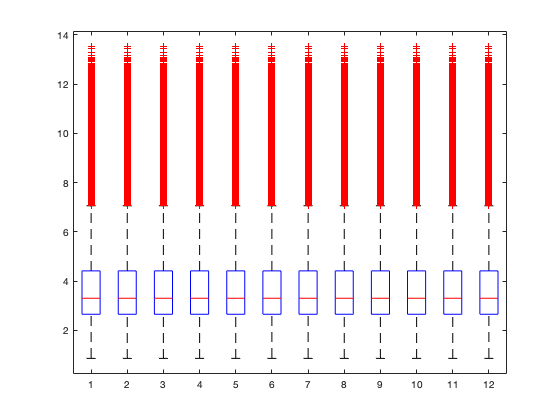

figure;
boxplot(normalised)

  3. We need to make a vector with the timepoints for each sample to be able to quickly extract the right samples. For instance, if we had 2 samples taken every 2 hours, and they were in order in the table we would say time = [0, 0, 2, 2, 4, 4, 6, 6, 8, 8]; Then we could get just the 6 hour samples by saying data(:,time==6)  

Make a time vector which will work with the  you have generated from the normalised data.

time = [0,0,0,8,8,8,24,24,24,32,32,32];
normalised(1, time==0)

ans =     5.8360    6.1345    5.8625


       4. As this is microarray data, all genes will have been given a measurement even if there was no RNA from that gene present in the sample.  In these cases we will have a measurement for the luminesence of a black spot.  This means that we have two distributions of values, one of the **expressed genes and one of the unexpressed genes**.  In this example the unexpressed genes are the main peak, and are Gaussianly distributed.  The expressed genes look like a long tail of higher values on this peak.

        Make a histogram of all gene measurements, label these two distributions, and pick a cutoff point between them.  

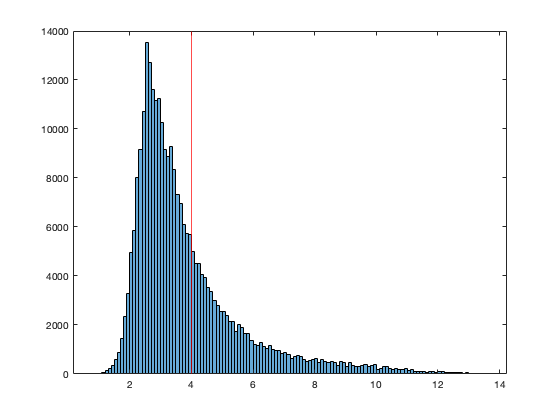

figure;
histogram(normalised)
% Cutoff when the guaussian ends
% Gaussian is the noise distrubution 
% One is guassian the other one is log % Right now they are overlapping
% The genes that have 

hold on
xline(4, 'Color','Red')
hold off

figure;

    5.  We now need to remove the unexpressed genes from the dataset.  But if a gene is expressed (has a value above your chosen cutoff) in all samples from a single timepoint, then it is interesting, even if it is unexpressed at other timepoints.

Find all the genes which are expressed in all samples of at least one timepoint.  How many are there?

col = ["Name";"Number"];
cutoff = 4;
expressed_table = {};
count = 0;
for j = 1: length(normalised)
    if all(normalised(j, time==0)>cutoff) || all(normalised(j, time==8)>cutoff) || all(normalised(j, time==24)>cutoff) || all(normalised(j, time==32)>cutoff)
         count = count + 1;
         expressed_table = [expressed_table, j];
    end 
end
count

count = 8034

% i is where the expressed gene was found. So expressed gene 4 was the 8th
% gene
expressed_table

expressed_table = 1×8034 cell array
  Columns 1 through 882

    {[1]}    {[3]}    {[4]}    {[8]}    {[9]}    {[10]}    {[13]}    {[15]}    {[17]}    {[18]}    {[19]}    {[20]}    {[21]}    {[22]}    {[27]}    {[28]}    {[29]}    {[31]}    {[34]}    {[35]}    {[40]}    {[41]}    {[43]}    {[44]}    {[45]}    {[46]}    {[47]}    {[49]}    {[50]}    {[51]}    {[53]}    {[56]}    {[57]}    {[63]}    {[64]}    {[66]}    {[67]}    {[68]}    {[70]}    {[71]}    {[72]}    {[73]}    {[75]}    {[76]}    {[79]}    {[80]}    {[84]}    {[85]}    {[86]}    {[87]}    {[88]}    {[89]}    {[94]}    {[95]}    {[97]}    {[98]}    {[100]}    {[101]}    {[103]}    {[105]}    {[106]}    {[107]}    {[108]}    {[109]}    {[112]}    {[113]}    {[114]}    {[115]}    {[117]}    {[124]}    {[125]}    {[127]}    {[129]}    {[131]}    {[133]}    {[134]}    {[135]}    {[136]}    {[138]}    {[139]}    {[141]}    {[146]}    {[149]}    {[150]}    {[151]}    {[153]}    {[155]}    {[158]}    {[162]}    {[164]}    {[166]

    6. We now want to find which of the expressed genes are differentially expressed after 8 hours.  In other words we are going to compare the samples at **0hrs with the samples at 8hrs and find the fold change and ttest p-value** (fdr corrected)

        a. Calculate the log (base 2) fold change for each expressed gene between 0hrs and 8hrs.  Remember the values are log base 2, so the fold change will be calculated with subtraction.

mat_expressed = normalised(cell2mat(expressed_table),:);
time_0 = mat_expressed(:,time==0);
time_8 = mat_expressed(:,time==8);

fold_changes = {};
for i = 1: length(time_0)
    diff_mean = mean(time_8(i,:))-mean(time_0(i,:));
    fold_changes = [fold_changes, diff_mean];
end
fold_changes = cell2mat(fold_changes)

fold_changes =     0.5468   -0.2212   -0.4225   -0.2447    0.2811    0.7941   -0.1959   -0.0643   -0.1527   -0.2884    0.4420    0.1800    0.0374    0.7618   -0.0199    0.0326    0.1705   -0.7462   -0.0028    0.1270    0.0016   -0.6844    0.2779    0.1620   -0.5058   -0.0166    0.1582   -0.2718    0.0614   -0.0168   -0.2780    0.2500   -0.1694   -0.8246   -0.5551   -0.8701   -1.0032    0.3578   -0.0902    0.0099    0.1641    0.0192    0.1768   -0.7491   -0.1520   -0.4564    0.3000    0.4405    0.2427   -0.0446


  b. Calculate the p-value from a ttest (**ttest2)** for each expressed genes between 0hrs and 8hrs.

[h,p] = ttest2(time_0', time_8')

h =      1     1     1     1     1     1     1     0     0     1     1     1     0     1     0     0     1     1     0     0     0     1     1     1     1     0     0     1     0     0     0     1     0     1     1     1     1     1     0     0     0     0     0     1     0     1     1     1     0     0


p =     0.0073    0.0301    0.0059    0.0343    0.0013    0.0002    0.0197    0.5872    0.1697    0.0372    0.0006    0.0271    0.6431    0.0001    0.8180    0.4952    0.0151    0.0041    0.9794    0.0831    0.9876    0.0004    0.0064    0.0332    0.0108    0.8985    0.1206    0.0386    0.4506    0.8697    0.1608    0.0452    0.0626    0.0028    0.0008    0.0005    0.0008    0.0085    0.1641    0.9169    0.2541    0.8238    0.1007    0.0004    0.0805    0.0171    0.0160    0.0001    0.1364    0.4656


c. Apply a muliple testing correction to your ttest p-values (**mafdr **with the BHFDR flag will do the Benjamini-Hochberg procedure we saw in the lecture).

adjusted_p = mafdr(p,'BHFDR','true')

adjusted_p =     0.0231    0.0630    0.0200    0.0694    0.0081    0.0032    0.0459    0.6512    0.2362    0.0733    0.0051    0.0582    0.7016    0.0025    0.8533    0.5666    0.0376    0.0158    0.9840    0.1346    0.9902    0.0042    0.0212    0.0677    0.0299    0.9195    0.1802    0.0753    0.5237    0.8953    0.2262    0.0846    0.1079    0.0125    0.0063    0.0047    0.0060    0.0253    0.2302    0.9336    0.3265    0.8583    0.1562    0.0044    0.1310    0.0416    0.0395    0.0023    0.1981    0.5384


        d. How many genes have both a log base 2 fold change >1 if upregulated or <-1 if downregulated (why these values?) and a significant (<0.05) p-value after correction?

upregulated = {};
downregulated = {};
for i=1:length(fold_changes)
    if fold_changes(i) > 1 && adjusted_p(i) < 0.05
        upregulated = [upregulated,adjusted_p(i)];
    end
    if fold_changes(i) < -1 && adjusted_p(i) < 0.05
        downregulated = [downregulated,adjusted_p(i)];
    end
end
upregulated

upregulated = 1×244 cell array
    {[0.0031]}    {[0.0080]}    {[0.0138]}    {[0.0025]}    {[0.0012]}    {[0.0032]}    {[0.0094]}    {[9.4657e-04]}    {[0.0030]}    {[8.3011e-04]}    {[0.0022]}    {[0.0027]}    {[0.0025]}    {[0.0027]}    {[0.0013]}    {[0.0043]}    {[0.0017]}    {[1.5297e-04]}    {[0.0015]}    {[0.0023]}    {[0.0013]}    {[0.0048]}    {[0.0070]}    {[0.0044]}    {[0.0012]}    {[9.4657e-04]}    {[0.0211]}    {[0.0020]}    {[0.0027]}    {[0.0025]}    {[0.0078]}    {[0.0073]}    {[0.0066]}    {[0.0058]}    {[8.3011e-04]}    {[0.0040]}    {[0.0042]}    {[0.0014]}    {[0.0044]}    {[0.0025]}    {[0.0034]}    {[4.0363e-04]}    {[0.0024]}    {[0.0012]}    {[7.4441e-04]}    {[0.0050]}    {[0.0024]}    {[0.0233]}    {[0.0152]}    {[0.0047]}    {[0.0068]}    {[0.0022]}    {[0.0029]}    {[0.0150]}    {[9.0229e-04]}    {[4.0363e-04]}    {[0.0019]}    {[0.0016]}    {[7.1487e-04]}    {[0.0014]}    {[0.0016]}    {[0.0038]}    {[0.0017]}    {[0.0021]}    {[0.0016]}    {[9.4657e-04]} 

downregulated

downregulated = 1×283 cell array
    {[0.0060]}    {[0.0051]}    {[0.0081]}    {[0.0044]}    {[0.0028]}    {[0.0039]}    {[0.0080]}    {[0.0075]}    {[0.0040]}    {[0.0027]}    {[0.0160]}    {[0.0030]}    {[0.0082]}    {[0.0256]}    {[0.0089]}    {[0.0074]}    {[0.0052]}    {[0.0097]}    {[0.0025]}    {[0.0028]}    {[0.0012]}    {[0.0022]}    {[0.0063]}    {[0.0024]}    {[0.0035]}    {[0.0015]}    {[0.0027]}    {[0.0044]}    {[0.0022]}    {[0.0274]}    {[0.0060]}    {[0.0172]}    {[0.0021]}    {[0.0027]}    {[0.0063]}    {[0.0012]}    {[0.0100]}    {[0.0061]}    {[9.4657e-04]}    {[0.0030]}    {[0.0023]}    {[0.0056]}    {[0.0072]}    {[0.0016]}    {[0.0100]}    {[0.0027]}    {[0.0043]}    {[9.4657e-04]}    {[0.0027]}    {[0.0146]}    {[0.0027]}    {[0.0094]}    {[0.0081]}    {[0.0042]}    {[0.0018]}    {[0.0040]}    {[0.0023]}    {[0.0200]}    {[0.0028]}    {[0.0013]}    {[0.0018]}    {[0.0053]}    {[0.0018]}    {[0.0072]}    {[0.0030]}    {[0.0028]}    {[0.0048]}    {[0.0030]}    {[0